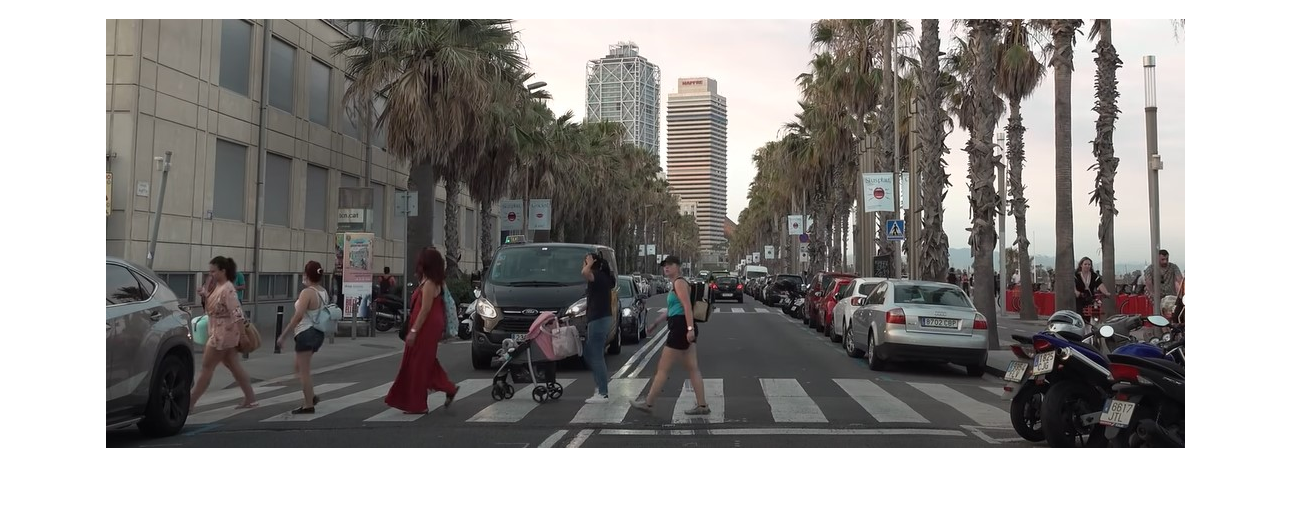

% ok lets gooooooooooooo!!!!!
% testim = imread("CV_zebracrossing_images/pic1.jpg");
% imshow(testim)

Imfolder = 'CV_zebracrossing_images';
if ~isfolder(Imfolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', Imfolder);
  uiwait(warndlg(errorMessage));
  return;  
end

% Get a list of all image files in the folder
imageFiles = dir(fullfile(Imfolder, '*.jpg')); 

imnum = numel(imageFiles);
images = cell(1, imnum);
imheight = zeros(1, imnum);
imcropheight = zeros(1, imnum);

for idx = 1:imnum
    filename = fullfile(Imfolder, imageFiles(idx).name);
    images{idx} = imread(filename);
    [~, imheight(idx), ~] = size(images{idx}); % Extract height of each image
    imcropped{idx} = imcrop(images{idx}, [1 1 size(images{idx}, 2) imheight(idx) * 0.5]);
end

for i = 1:imnum
    imshow(imcropped{i});
end